%% Simulation Parameters
fs = 100000;         % Sampling frequency (Hz)
fc = 10000;          % Carrier frequency (Hz)
M = 16;              % Modulation order (16-QAM)
sps = 20;            % Samples per symbol
SNR = 20;            % Signal-to-Noise Ratio (dB)
k = log2(M);         % Bits per symbol    formula : log_2(M) = bits
numSymbols = 1000;   % Number of symbols

% Calculate time vector
T = numSymbols * sps / fs;
t = 0:1/fs:T - 1/fs;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Transmitter %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Generate random bits and map to symbols
dataInBits = randi([0 1], numSymbols*k, 1);
dataIn = bi2de(reshape(dataInBits, k, [])', 'left-msb');
txSym = qammod(dataIn, M, 'UnitAveragePower', true);

% Upsample and pulse shape
txUp = upsample(txSym, sps);
rolloff = 0.25; span = 10;
rrcFilter = rcosdesign(rolloff, span, sps);
txShaped = filter(rrcFilter, 1, txUp);

% Create I/Q components
I = real(txShaped);
Q = imag(txShaped);

% Generate carriers
t_filt = t(1:length(I));
carrier_I = cos(2*pi*fc*t_filt)';
carrier_Q = sin(2*pi*fc*t_filt)';

% Modulate onto carrier
mod_I = I .* carrier_I;
mod_Q = Q .* carrier_Q;
qam_signal = mod_I + mod_Q;

%% Channel
qam_signal_noisy = awgn(qam_signal, SNR, 'measured');

%% Receiver
% Demodulate carriers
demod_I = qam_signal_noisy .* carrier_I;
demod_Q = qam_signal_noisy .* carrier_Q;

% Low-pass filter to extract baseband
cutoff = fc / 2;
[b, a] = butter(6, cutoff / (fs / 2));
base_I = filter(b, a, demod_I);
base_Q = filter(b, a, demod_Q);

% Matched filtering
matched_I = filter(rrcFilter, 1, base_I);
matched_Q = filter(rrcFilter, 1, base_Q);

% Delay compensation
totalDelay = 2 * span * sps;
matched_I = matched_I(totalDelay+1:end);
matched_Q = matched_Q(totalDelay+1:end);

% Downsample
rx_I = downsample(matched_I, sps);
rx_Q = downsample(matched_Q, sps);

% Reconstruct complex baseband signal
rxSig = rx_I + 1i*rx_Q;

% Demodulate symbols
rxData = qamdemod(rxSig, M, 'UnitAveragePower', true);
dataOutBits = de2bi(rxData, k, 'left-msb')';
dataOutBits = dataOutBits(:);

%% BER Calculation
minLen = min(length(dataInBits), length(dataOutBits));
ber = sum(dataInBits(1:minLen) ~= dataOutBits(1:minLen)) / minLen;
fprintf('Bit Error Rate = %e, Number of Errors = %d\n', ber, ber*minLen);

Bit Error Rate = 5.020408e-01, Number of Errors = 1968


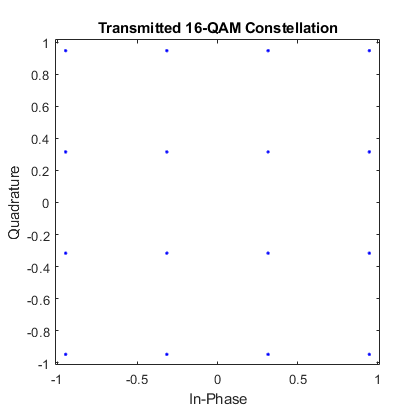


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Visualization %%%%%%%%%%%%%%%%%%%%%%%%
% Transmitted Constellation
figure;
scatterplot(txSym);
title('Transmitted 16-QAM Constellation');

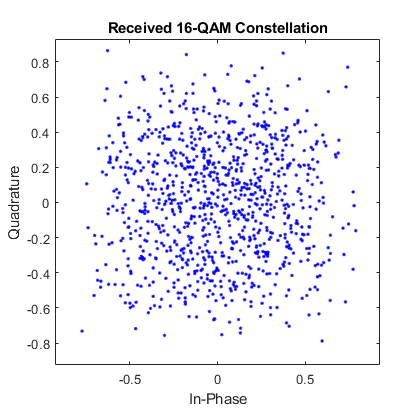


% Received Constellation
figure;
scatterplot(rxSig);
title('Received 16-QAM Constellation');

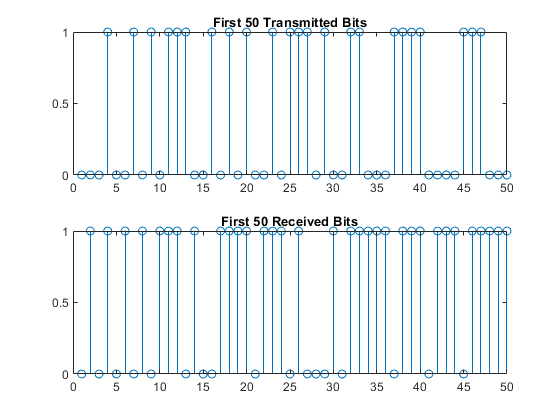


% Bit Comparison
figure;
subplot(2,1,1); stem(dataInBits(1:50)); title('First 50 Transmitted Bits');
subplot(2,1,2); stem(dataOutBits(1:50)); title('First 50 Received Bits');

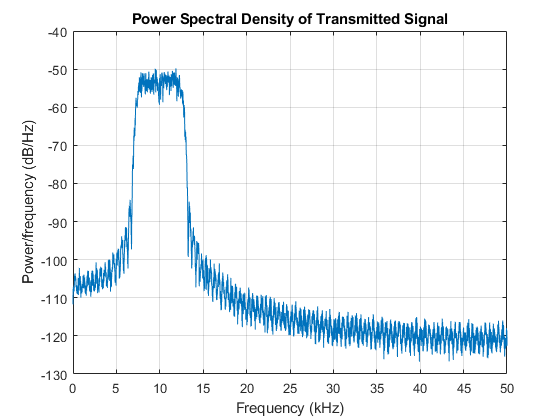


% Spectrum
figure;
pwelch(qam_signal, [], [], [], fs);
title('Power Spectral Density of Transmitted Signal');

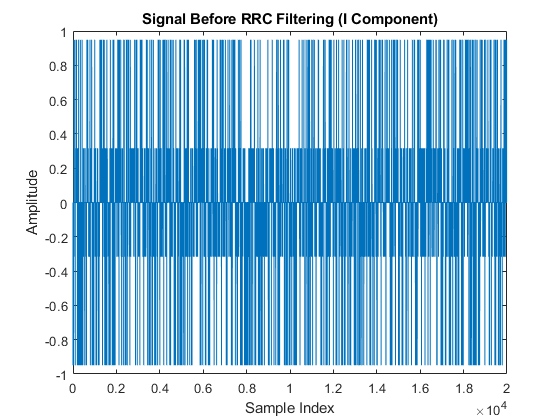

% Upsample and pulse shape
txUp = upsample(txSym, sps);
rolloff = 0.25; span = 10;
rrcFilter = rcosdesign(rolloff, span, sps);

% Signal Before Filtering ===
figure;
plot(real(txUp));
title('Signal Before RRC Filtering (I Component)');
xlabel('Sample Index');
ylabel('Amplitude');

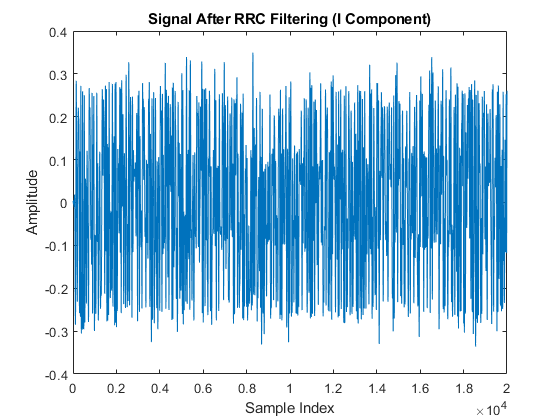


% Apply RRC filter
txShaped = filter(rrcFilter, 1, txUp);

% Signal After Filtering ===
figure;
plot(real(txShaped));
title('Signal After RRC Filtering (I Component)');
xlabel('Sample Index');
ylabel('Amplitude');